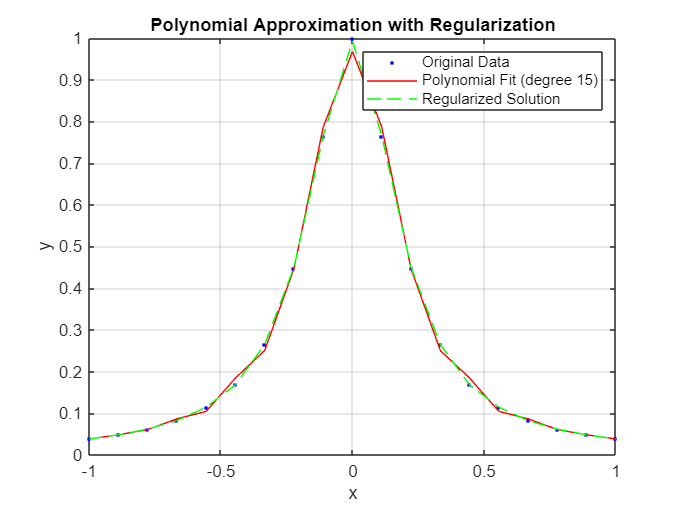

% Load the dataset
load('RungeTikhonov.mat'); 


% Part a: Polynomial approximation using a polynomial of degree 15
degree = 15;
p = polyfit(x, y, degree);
y_fit = polyval(p, x(:)); % Ensure `x` is treated as a column vector


% Part b: Add a regularizing term on the second derivative
lambda = 1e-2; % Regularization parameter
n = length(x);

% Construct second derivative matrix
D2 = diag(ones(n-1,1), 1) - 2*diag(ones(n,1)) + diag(ones(n-1,1), -1);
D2 = D2(2:end-1, :); % Adjust dimensions

% Regularized solution
x = x(:);
y = y(:);

% Construct A and b
A = [eye(n); sqrt(lambda) * D2];
b = [y; zeros(size(D2, 1), 1)];

% Regularized solution
regularized_solution = A \ b;


% Part c: Plot the results
figure;
plot(x, y, 'b.', 'DisplayName', 'Original Data');
hold on;
plot(x, y_fit, 'r-', 'DisplayName', 'Polynomial Fit (degree 15)');
plot(x, regularized_solution(1:n), 'g--', 'DisplayName', 'Regularized Solution');
legend show;
title('Polynomial Approximation with Regularization');
xlabel('x');
ylabel('y');
grid on;

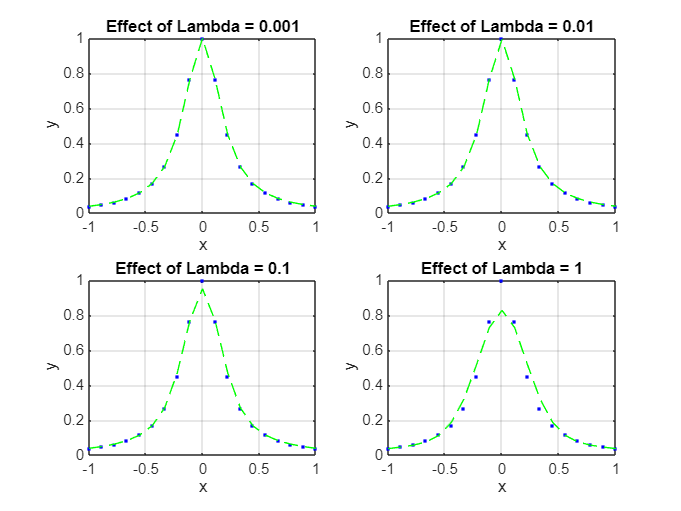


% Part d: Change lambda and discuss effects
lambdas = [1e-3, 1e-2, 1e-1, 1]; % Test various lambda values
figure;
for i = 1:length(lambdas)
    lambda = lambdas(i);
    A = [eye(n); sqrt(lambda) * D2];
    b = [y; zeros(size(D2, 1), 1)];
    regularized_solution = A \ b;

    subplot(2, 2, i);
    plot(x, y, 'b.', 'DisplayName', 'Original Data');
    hold on;
    plot(x, regularized_solution(1:n), 'g--', 'DisplayName', ['Lambda = ', num2str(lambda)]);
    title(['Effect of Lambda = ', num2str(lambda)]);
    xlabel('x');
    ylabel('y');
    grid on;
end

**Discussion on Part**

- **Small **lambda **(e.g., **10^−3**):**

- The solution closely matches the data points.

- Risk of oscillations or overfitting, particularly with noisy data.

- **Moderate **lambda **(e.g., 1****0^−****2****):**

- Balances smoothness and data fidelity.

- Effective for reducing noise while preserving features.

- **Large **lambda** (e.g., 1****0^−****1**** or 1****):**

- The solution becomes progressively smoother.

- Significant underfitting occurs as the solution deviates from the data.

**Visual Results**

- The plots from the `subplot` will show how the solution transitions from closely matching the data (small lambda) to being oversmoothed (large lambda).

- Observing these trends helps choose an optimal lambda value for the specific application.

## Exercise 2: 2D Tikhonov Regularization

% Load the dataset
data = readmatrix('SingleCell_D.csv'); 

% Check the size of the dataset
disp(size(data));

   438    30




% If the dataset has non-numeric fields, clean it
% Remove rows with NaN or non-numeric values
data = data(all(~isnan(data), 2), :);


% Part a: Identify a row with external pressure and reshape
external_row = 100; 
matrix_data = reshape(data(external_row, :), [6, 5]);

% Part b: Tikhonov regularization on the first derivative
%lambda = 1e-2; % Regularization parameter


% Regularize along X-direction
% Reshape data into a vector
data_vector = matrix_data(:); % Convert 6x5 matrix to 30x1 vector

% Construct derivative matrix for X-direction
D_x = diag(ones(5-1, 1), 1) - diag(ones(5, 1)); % 5x5 derivative operator
D_x = D_x(1:end-1, :); % Trim to 4x5

% Regularization matrix (apply to all rows in X-direction)
lambda = 1e-2; % Regularization parameter
A_x = [eye(length(data_vector)); sqrt(lambda) * kron(eye(6), D_x)]; % Combine identity + reg

% Adjust b_x dimensions
b_x = [data_vector; zeros(size(D_x, 1) * size(matrix_data, 1), 1)]; % Match rows of A_x



disp(size(A_x)); % Rows: [30 (data) + 24 (reg)] x 30 columns

    54    30



disp(size(b_x)); % Rows: [30 (data) + 24 (zeros)] x 1

    54     1



% Solve regularized system
regularized_x = A_x \ b_x;

% Reshape result back to matrix form
smoothed_matrix = reshape(regularized_x(1:length(data_vector)), size(matrix_data));


% Regularization in y-direction
% Flatten data into a vector
data_vector = matrix_data(:); % 6x5 matrix reshaped to 30x1 vector

% Construct derivative matrix for Y-direction
D_y = diag(ones(6-1, 1), 1) - diag(ones(6, 1)); % 6x6 derivative operator
D_y = D_y(1:end-1, :); % Trim to 5x6

% Regularization matrix (apply to all columns in Y-direction)
lambda = 1e-2; % Regularization parameter
A_y = [eye(length(data_vector)); sqrt(lambda) * kron(D_y, eye(5))]; % Combine identity + reg

% Adjust b_y dimensions
b_y = [data_vector; zeros(size(D_y, 1) * size(matrix_data, 2), 1)]; % Match rows of A_y

disp(size(A_y)); % Should be [(30 + 25) x 30]

    55    30



disp(size(b_y)); % Should be [(30 + 25) x 1]

    55     1



% Solve regularized system
regularized_y = A_y \ b_y;

% Reshape result back to matrix form
smoothed_matrix_y = reshape(regularized_y(1:length(data_vector)), size(matrix_data));

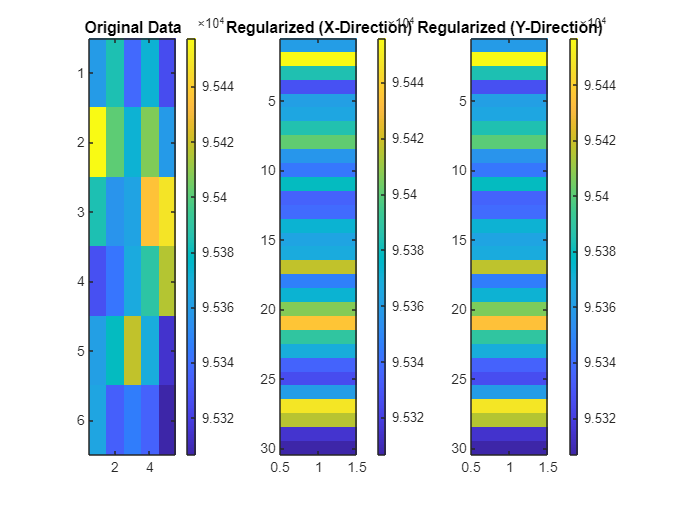

% Visualize results
figure;
subplot(1, 3, 1);
imagesc(matrix_data);
title('Original Data');
colorbar;

subplot(1, 3, 2);
imagesc(regularized_x);
title('Regularized (X-Direction)');
colorbar;

subplot(1, 3, 3);
imagesc(regularized_y);
title('Regularized (Y-Direction)');
colorbar;